# Finding roundworm edges

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity. 

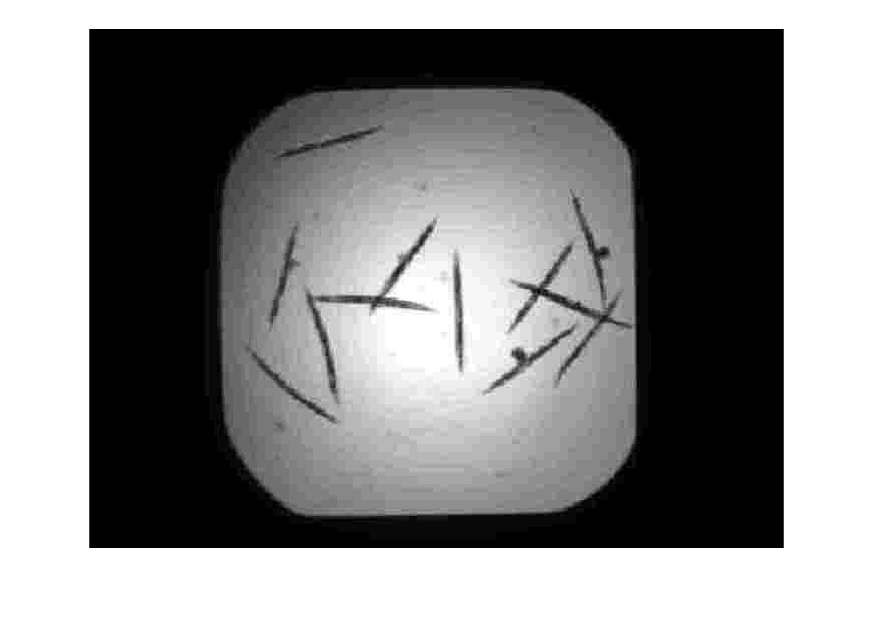

worms = imread("./images/worms.jpg");
imshow(worms)

## Task 1

Now that you know how to use the `edge` function, you can apply it to locate roundworms.

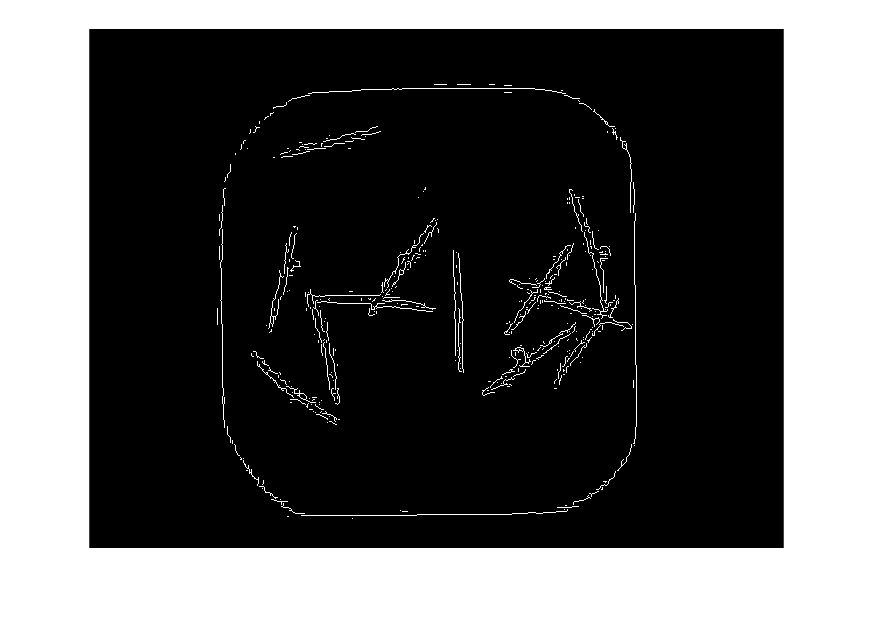

[wormsEdge, thresh] = edge(worms);
imshow(wormsEdge)

## Task 2

Looks like there's some background noise captured both inside and around the worms. Try setting a higher threshold to avoid capturing weaker edges.

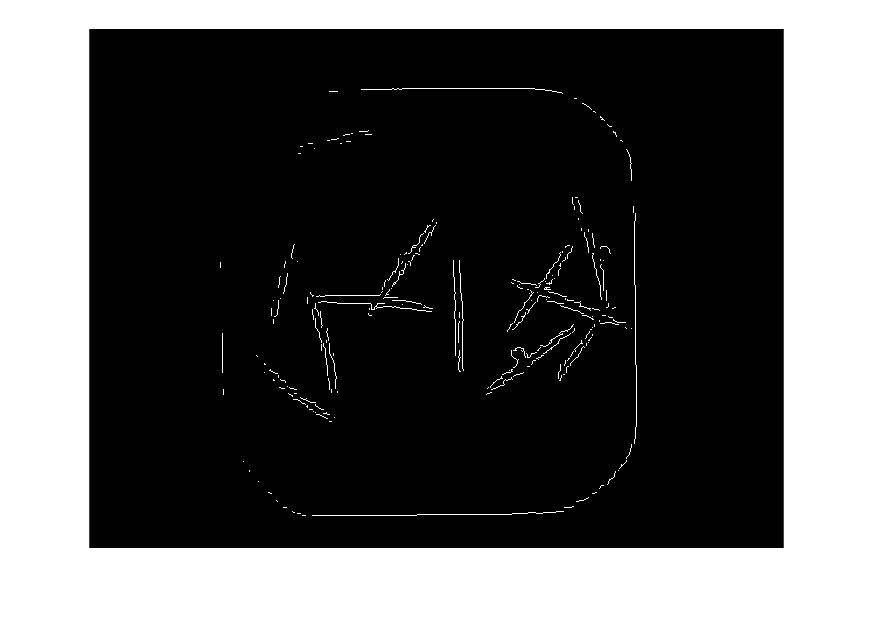

wormsEdge = edge(worms, 2*thresh);
imshow(wormsEdge)

## Task 3

That eliminated the noise, but it looks like some worm edges were fractured in the process. In cases where setting the threshold alone isn't enough, it's worth trying a different edge finding algorithm.

`[``BW``,``threshOut``]` `=` `edge``(``I``,``method``)`

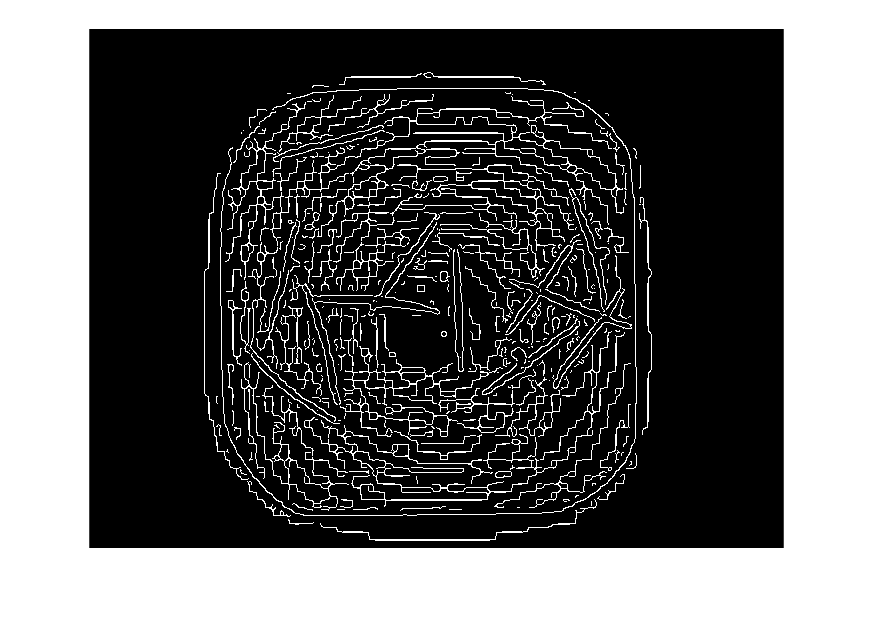

[wormsEdge, thresh] = edge(worms, "Canny");
imshow(wormsEdge)

## Task 4

With the default thresholds, the Canny method is a bit overzealous for these worms. You can specify a two-element threshold when using the Canny method to fine-tune which edges are found.

`[``BW``,``threshOut``]` `=` `edge``(``I``,``"Canny"``,``[``low` `high``])``;`

You can increase the high threshold to reduce the number of strong edges found in the initial pass.

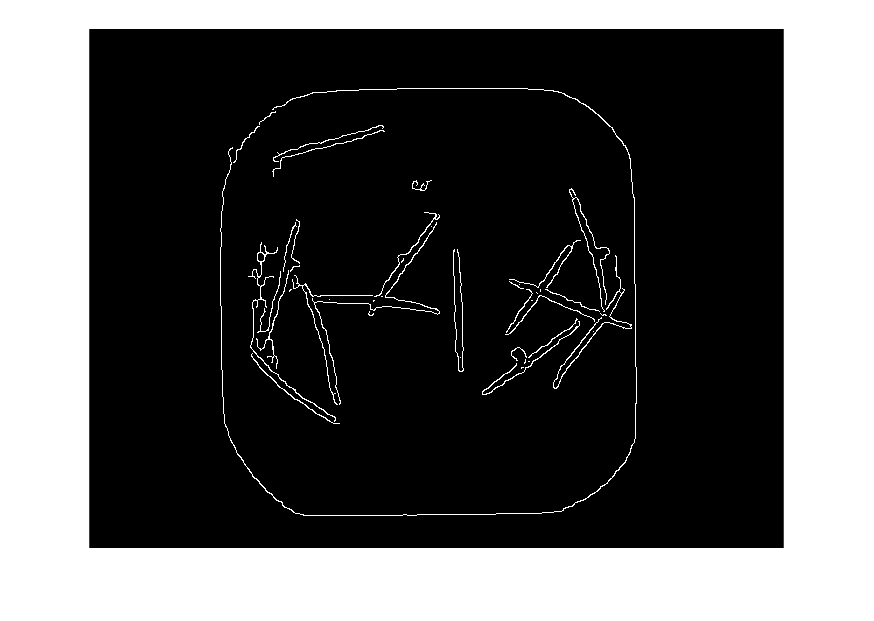

wormsEdge = edge(worms, "Canny", [thresh(1) 0.2]);
imshow(wormsEdge)

## Task 5

That worked but you might notice there's some "stringing" at the ends of a few worms. This occurred because the low threshold is too low, causing extraneous faint edges to be identified because of their connection to the stronger worm edges. You can increase the low threshold to avoid picking up these undesirable edges.

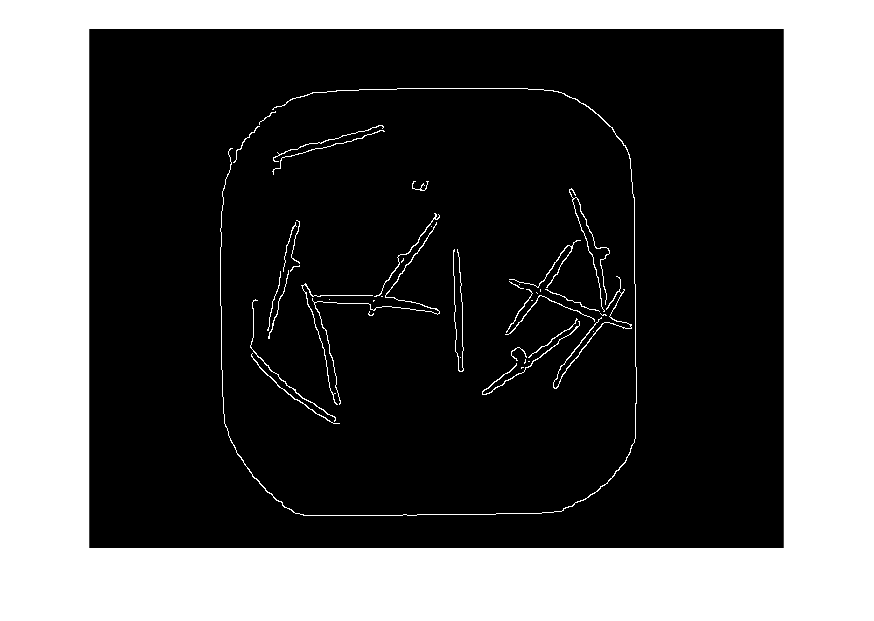

wormsEdge = edge(worms, "Canny", [0.06 0.2]);
imshow(wormsEdge)